## Cue only ! dummy coding

## Pain  cue

#### Pain :: load dataset

mount_dir = '/Volumes/spacetop_projects_social/analysis/fmri/spm/univariate/model-02_CcEScsA_24dofcsd/1stLevel';
con_list = dir(fullfile(mount_dir, '*/con_0021.nii'));
spm('Defaults','fMRI') 
con_fldr = {con_list.folder}; fname = {con_list.name};
con_files = strcat(con_fldr,'/', fname)';
con_data_obj = fmri_data(con_files);

Using default mask: /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
Direct calls to spm_defauts are deprecated.
Please use spm('Defaults',modality) or spm_get_defaults instead.


sampleto = '/Volumes/spacetop_projects_social/analysis/fmri/spm/univariate/model-02_CcEScsA_24dofcsd/1stLevel/sub-0007/con_0021.nii'

loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 23960880 bytes
Loading image number:    60
Elapsed time is 5.530679 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 5785735  Bit rate: 22.46 bits


contrast_name = {'cue_P', 'cue_V', 'cue_C',...
    'cueXcue_P', 'cueXcue_V', 'cueXcue_C',...
    'stim_P', 'stim_V', 'stim_C',...
    'stimXcue_P', 'stimXcue_V', 'stimXcue_C',...
    'stimXint_P', 'stimXint_V', 'stimXint_C',...
    'motor', ...
    'simple_cue_P', 'simple_cue_V', 'simple_cue_C','simple_cue_G',...
    'simple_cueXcue_P', 'simple_cueXcue_V', 'simple_cueXcue_C','simple_cueXcue_G', ...
    'simple_stim_P', 'simple_stim_V', 'simple_stim_C','simple_stim_G',...
    'simple_stimXcue_P', 'simple_stimXcue_V', 'simple_stimXcue_C','simple_stimXcue_G',...
    'simple_stimXint_P', 'simple_stimXint_V','simple_stimXint_C', 'simple_stimXint_G'};


#### Pain :: `check data coverage`

m = mean(con_data_obj);
m.dat = sum(~isnan(con_data_obj.dat) & con_data_obj.dat ~= 0, 2);
orthviews(m, 'trans') % display

SPM12: spm_check_registration (v7759)              14:47:45 - 01/06/2022
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


Grouping contiguous voxels:   1 regions


ans = 1×1 cell array
    {1×1 region}


#### Pain :: Plot diagnostics, before l2norm

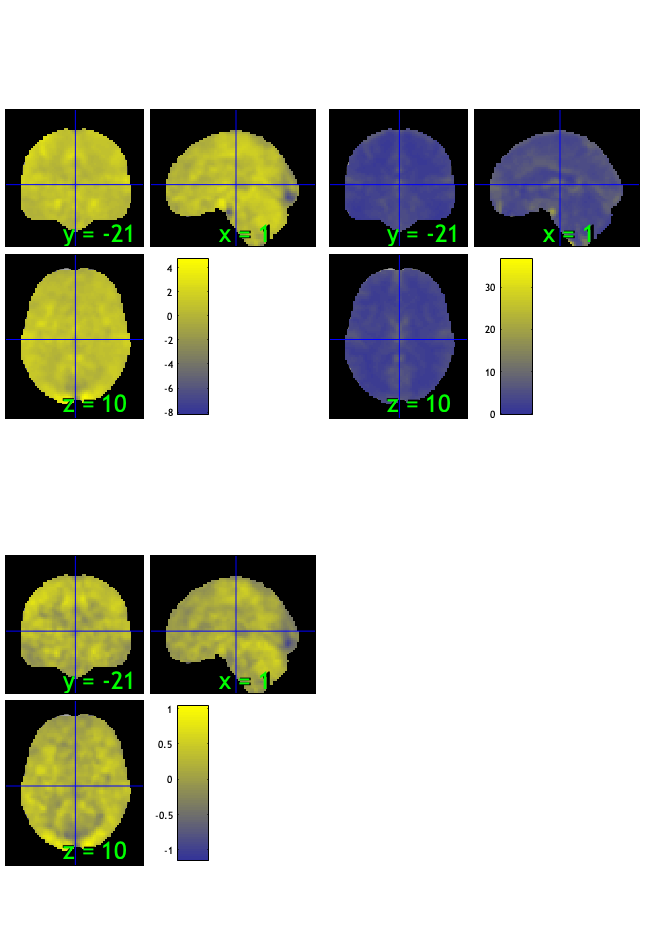

______________________________________________________________
Outlier analysis
______________________________________________________________
global mean | global mean to var | spatial MAD | Missing values |   0 images 


Retained 3 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 25.00%
Expected 3.00 outside 95% ellipsoid, found   5

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 3 images		Cases 6 36 47 
Uncorrected: 5 images		Cases 6 14 32 36 47 

Retained 8 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 60.00%
Expected 3.00 outside 95% ellipsoid, found   0

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 0 images		Cases  
Uncorrected: 0 images		Cases  

Mahalanobis (cov and corr, q<0.05 corrected):
  3 images 
                               Outlier_count    Percentage
                               ___

SPM12: spm_check_registration (v7759)              14:48:08 - 01/06/2022
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1
 (all)  

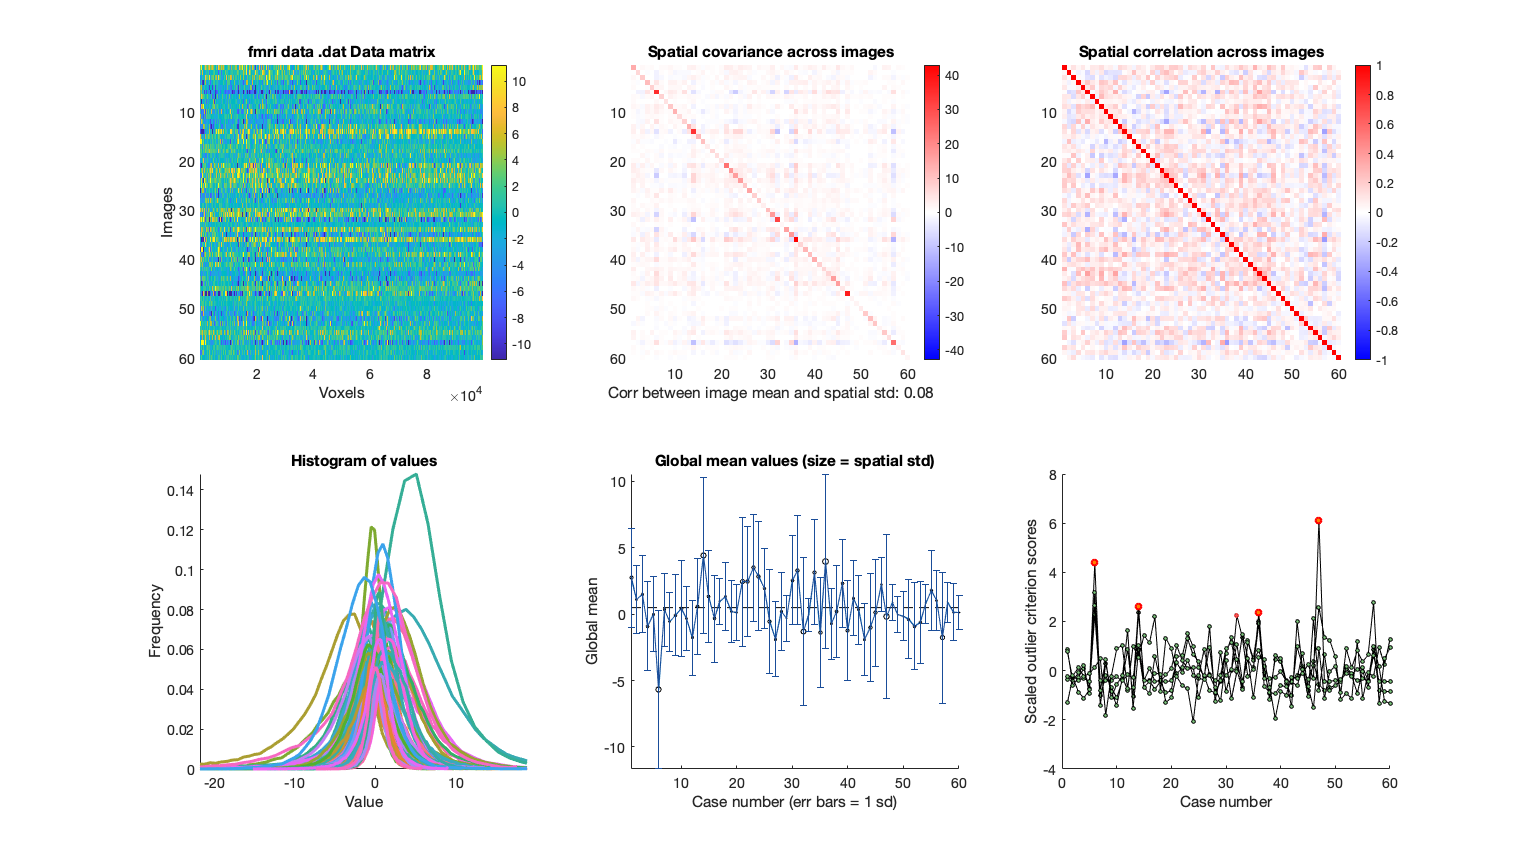

Grouping contiguous voxels:   1 regions


Grouping contiguous voxels:   1 regions


Grouping contiguous voxels:   1 regions


wh_outlier_uncorr = 60×1 logical array
   0
   0
   0
   0
   0
   1
   0
   0
   0
   0


wh_outlier_corr = 60×1 logical array
   0
   0
   0
   0
   0
   1
   0
   0
   0
   0


drawnow; snapnow

[wh_outlier_uncorr, wh_outlier_corr] = plot(con_data_obj)

#### Pain :: run robfit

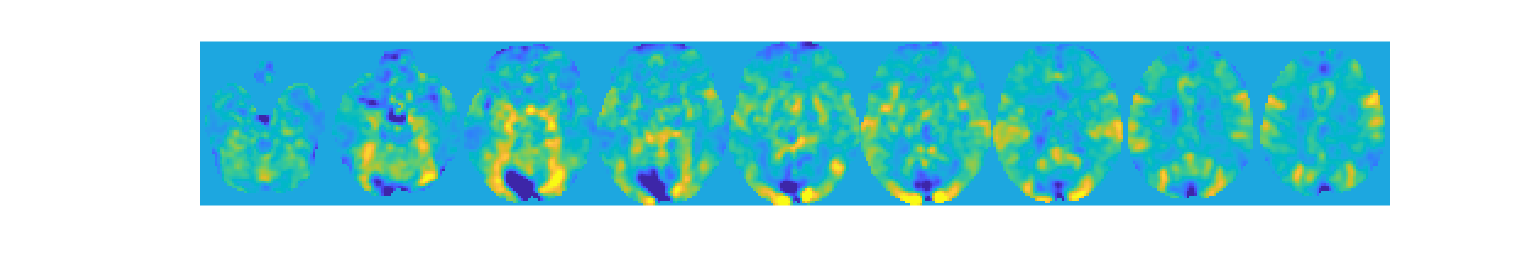

set(gcf,'Visible','on')

figure ('Visible', 'on');
drawnow, snapnow;

#### Pain :: remove outliers based on plot

con = con_data_obj;
disp(strcat("current length is ", num2str(size(con_data_obj.dat,2))))

current length is 60


%for s = 1:length(wh_outlier_corr)
    %disp(strcat("-------subject", num2str(s), "------"))
con.dat = con_data_obj.dat(:,~wh_outlier_corr);
con.image_names = con_data_obj.image_names(~wh_outlier_corr,:)

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×56 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [56×12 char]
              fullpath: [60×119 char]
           files_exist: [60×1 logical]
               history:

con.fullpath = con_data_obj.fullpath(~wh_outlier_corr,:)

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×56 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [56×12 char]
              fullpath: [56×119 char]
           files_exist: [60×1 logical]
               history:

con.files_exist = con_data_obj.files_exist(~wh_outlier_corr,:)

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×56 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [56×12 char]
              fullpath: [56×119 char]
           files_exist: [56×1 logical]
               history:

%end
disp(strcat("after removing ", num2str(sum(wh_outlier_corr)), " participants, size is now ",num2str(size(con.dat,2))))

after removing 4 participants, size is now 56


#### Pain :: plot diagnostics, after l2norm

imgs2 = con.rescale('l2norm_images');

#### Pain :: ttest

t = ttest(imgs2);

One-sample t-test
Calculating t-statistics and p-values


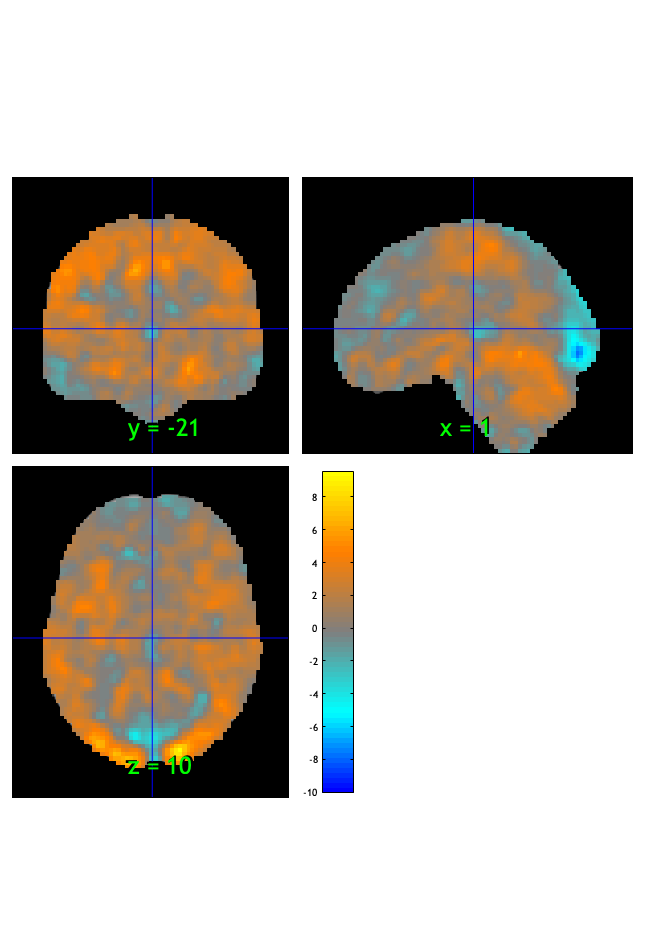

SPM12: spm_check_registration (v7759)              14:48:13 - 01/06/2022
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


ans = 1×1 cell array
    {1×1 struct}


orthviews(t)

drawnow, snapnow;

fdr_t = threshold(t, .05, 'fdr');

Image   1 FDR q < 0.050 threshold is 0.010288

Image   1
 66 contig. clusters, sizes   1 to 19226
Positive effect: 19808 voxels, min p-value: 0.00000000
Negative effect: 736 voxels, min p-value: 0.00000000


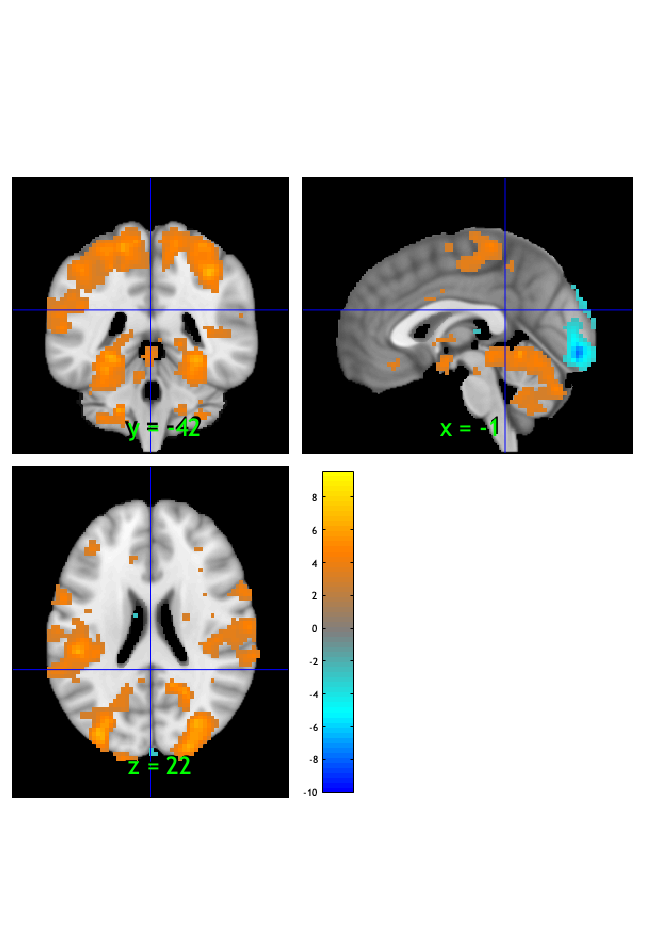

SPM12: spm_check_registration (v7759)              14:48:15 - 01/06/2022
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


ans = 1×1 cell array
    {1×66 struct}


orthviews(fdr_t)

drawnow, snapnow;

create_figure('montage'); axis off
montage(fdr_t)

Setting up fmridisplay objects


sagittal montage: 340 voxels displayed, 20204 not displayed on these slices


sagittal montage: 288 voxels displayed, 20256 not displayed on these slices


sagittal montage: 340 voxels displayed, 20204 not displayed on these slices


axial montage: 3361 voxels displayed, 17183 not displayed on these slices


axial montage: 3719 voxels displayed, 16825 not displayed on these slices


ans =   fmridisplay with properties:

            overlay: '/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img'
              SPACE: [1×1 struct]
    activation_maps: {[1×1 struct]}
            montage: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
            surface: {}
          orthviews: {}
            history: {}
    history_descrip: []
    additional_info: ''


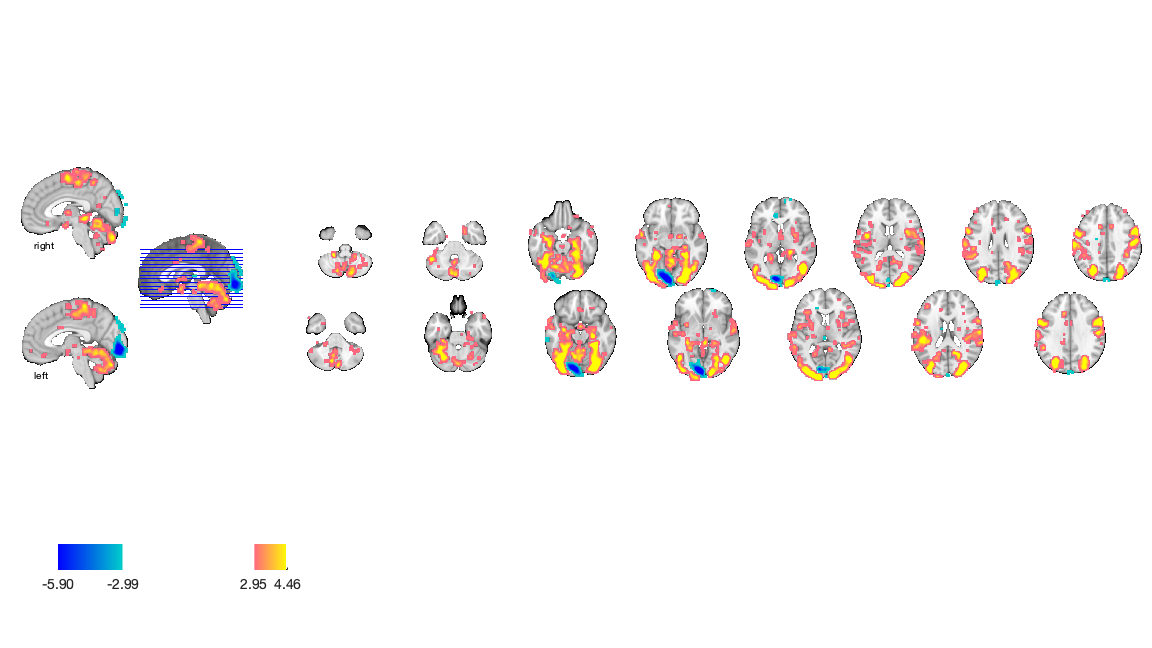

drawnow, snapnow;

## Vicarious  cue

clear all

#### Vicarious  :: load dataset

mount_dir = '/Volumes/spacetop_projects_social/analysis/fmri/spm/univariate/model-02_CcEScsA_24dofcsd/1stLevel';
con_list = dir(fullfile(mount_dir, '*/con_0022.nii'));
spm('Defaults','fMRI') 
con_fldr = {con_list.folder}; fname = {con_list.name};
con_files = strcat(con_fldr,'/', fname)';
con_data_obj = fmri_data(con_files);

Using default mask: /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
Direct calls to spm_defauts are deprecated.
Please use spm('Defaults',modality) or spm_get_defaults instead.


sampleto = '/Volumes/spacetop_projects_social/analysis/fmri/spm/univariate/model-02_CcEScsA_24dofcsd/1stLevel/sub-0007/con_0022.nii'

loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 23960880 bytes
Loading image number:    60
Elapsed time is 5.901843 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 5790161  Bit rate: 22.47 bits


contrast_name = {'cue_P', 'cue_V', 'cue_C',...
    'cueXcue_P', 'cueXcue_V', 'cueXcue_C',...
    'stim_P', 'stim_V', 'stim_C',...
    'stimXcue_P', 'stimXcue_V', 'stimXcue_C',...
    'stimXint_P', 'stimXint_V', 'stimXint_C',...
    'motor', ...
    'simple_cue_P', 'simple_cue_V', 'simple_cue_C','simple_cue_G',...
    'simple_cueXcue_P', 'simple_cueXcue_V', 'simple_cueXcue_C','simple_cueXcue_G', ...
    'simple_stim_P', 'simple_stim_V', 'simple_stim_C','simple_stim_G',...
    'simple_stimXcue_P', 'simple_stimXcue_V', 'simple_stimXcue_C','simple_stimXcue_G',...
    'simple_stimXint_P', 'simple_stimXint_V','simple_stimXint_C', 'simple_stimXint_G'};

#### Vicarious  :: `check data coverage`

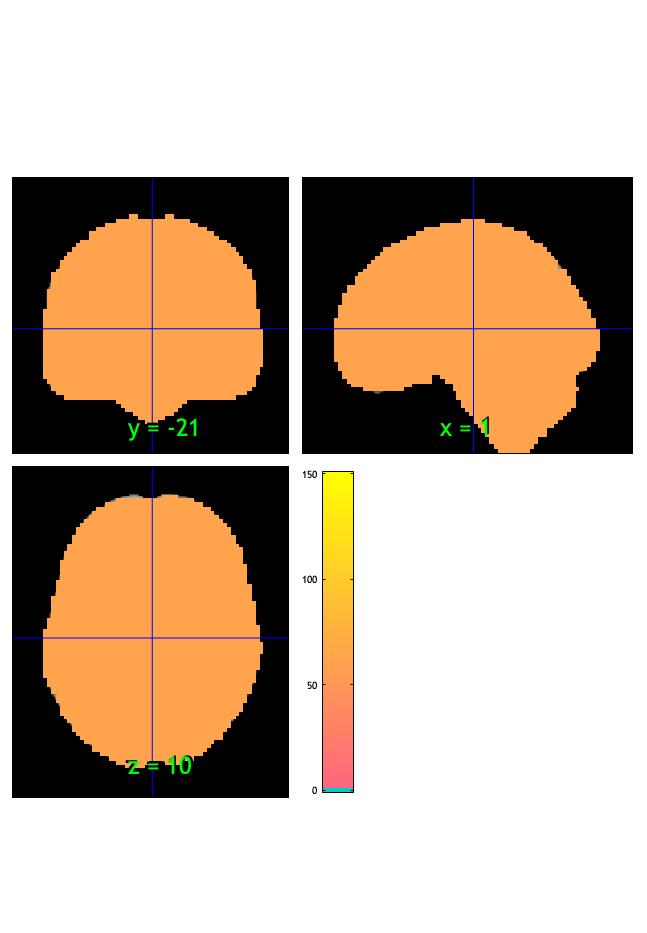

SPM12: spm_check_registration (v7759)              14:48:30 - 01/06/2022
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


Grouping contiguous voxels:   1 regions


ans = 1×1 cell array
    {1×1 region}


m = mean(con_data_obj);
m.dat = sum(~isnan(con_data_obj.dat) & con_data_obj.dat ~= 0, 2);
orthviews(m, 'trans') % display

#### Vicarious  :: Plot diagnostics, before l2norm

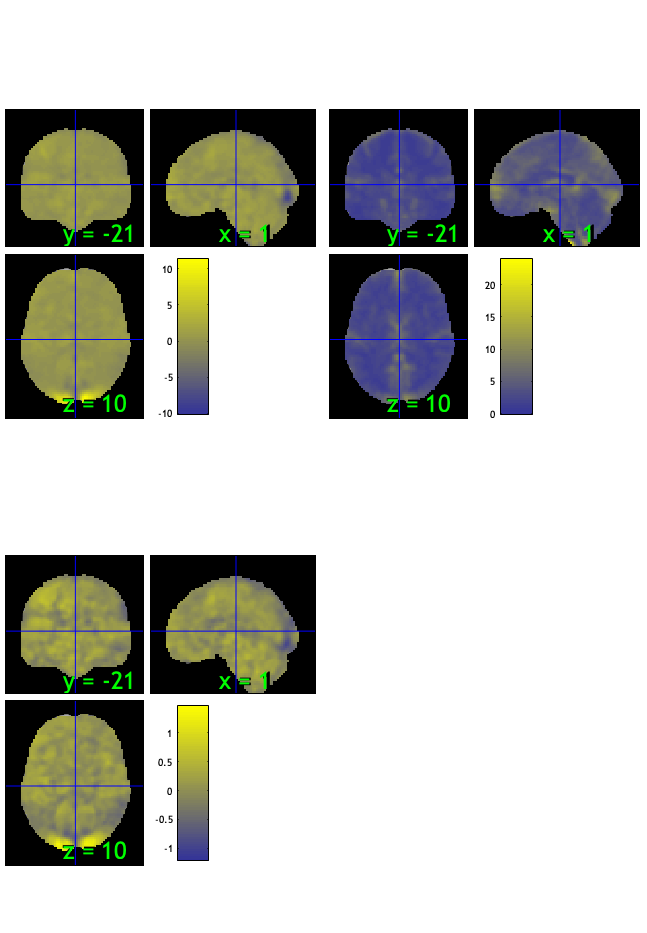

______________________________________________________________
Outlier analysis
______________________________________________________________
global mean | global mean to var | spatial MAD | Missing values |   0 images 


Retained 3 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 33.33%
Expected 3.00 outside 95% ellipsoid, found   5

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 1 images		Cases 14 
Uncorrected: 5 images		Cases 10 13 14 35 38 

Retained 13 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 53.33%
Expected 3.00 outside 95% ellipsoid, found   1

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 0 images		Cases  
Uncorrected: 1 images		Cases 60 

Mahalanobis (cov and corr, q<0.05 corrected):
  1 images 
                               Outlier_count    Percentage
                               ____

SPM12: spm_check_registration (v7759)              14:48:53 - 01/06/2022
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1
 (all)  

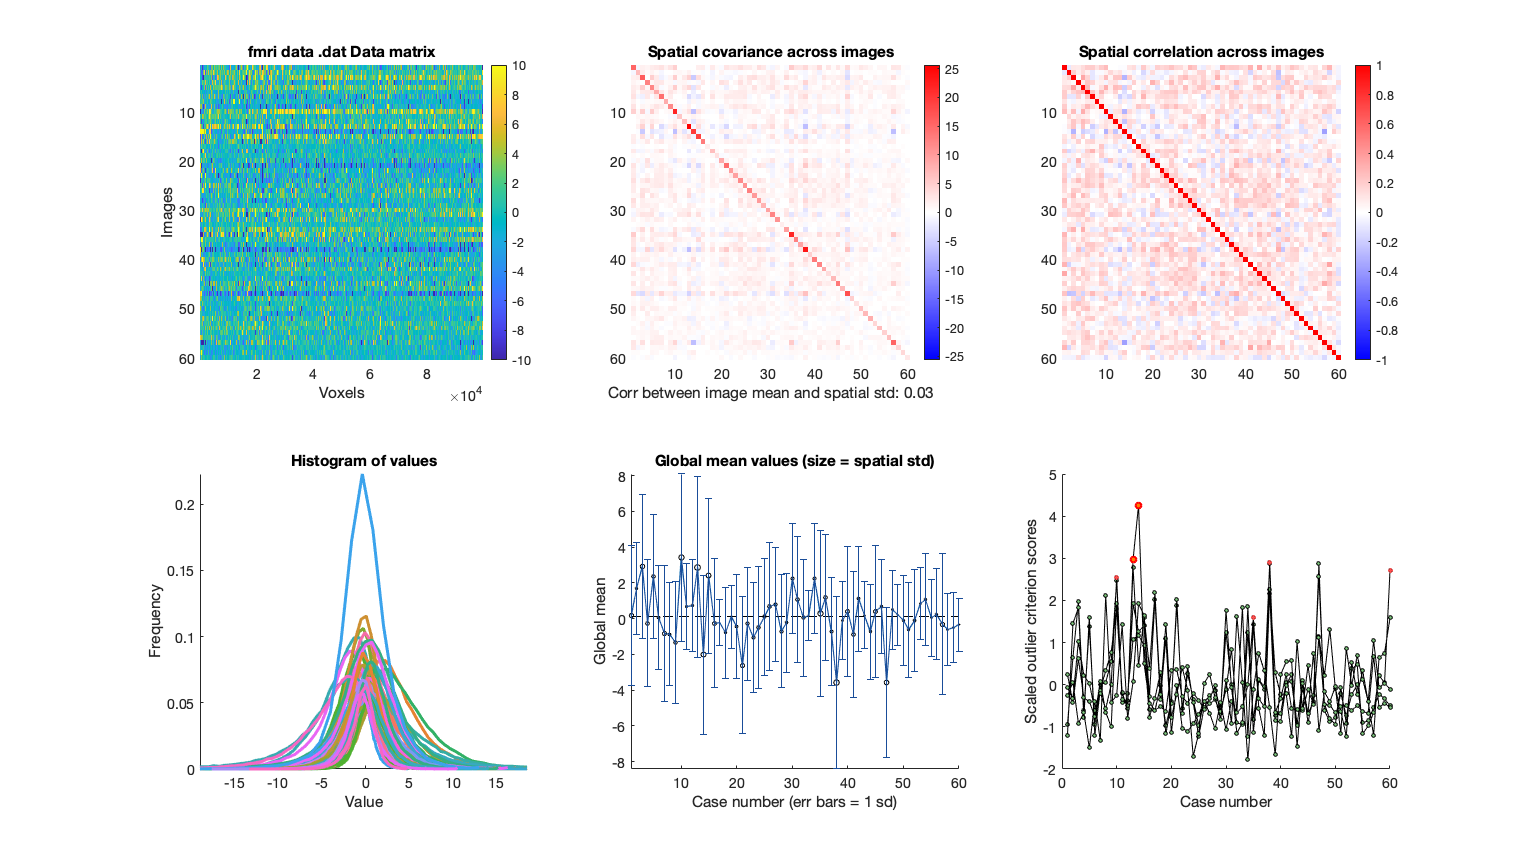

Grouping contiguous voxels:   1 regions


Grouping contiguous voxels:   1 regions


Grouping contiguous voxels:   1 regions


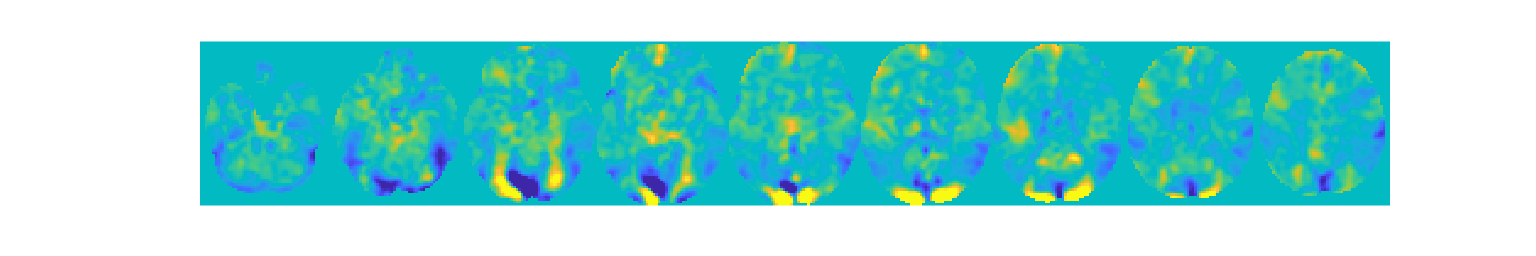

wh_outlier_uncorr = 60×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   1


wh_outlier_corr = 60×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


drawnow; snapnow

[wh_outlier_uncorr, wh_outlier_corr] = plot(con_data_obj)

#### Vicarious  :: run robfit

set(gcf,'Visible','on')
figure ('Visible', 'on');
drawnow, snapnow;

#### Vicarious  :: remove outliers based on plot

con = con_data_obj;
disp(strcat("current length is ", num2str(size(con_data_obj.dat,2))))

current length is 60


%for s = 1:length(wh_outlier_corr)
  %  disp(strcat("-------subject", num2str(s), "------"))
con.dat = con_data_obj.dat(:,~wh_outlier_corr);
con.image_names = con_data_obj.image_names(~wh_outlier_corr,:)

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×58 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [58×12 char]
              fullpath: [60×119 char]
           files_exist: [60×1 logical]
               history:

con.fullpath = con_data_obj.fullpath(~wh_outlier_corr,:)

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×58 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [58×12 char]
              fullpath: [58×119 char]
           files_exist: [60×1 logical]
               history:

con.files_exist = con_data_obj.files_exist(~wh_outlier_corr,:)

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×58 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [58×12 char]
              fullpath: [58×119 char]
           files_exist: [58×1 logical]
               history:

%end
disp(strcat("after removing ", num2str(sum(wh_outlier_corr)), " participants, size is now ",num2str(size(con.dat,2))))

after removing 2 participants, size is now 58


#### Vicarious  :: plot diagnostics, after l2norm

imgs2 = con.rescale('l2norm_images');

#### Vicarious  :: ttest

t = ttest(imgs2);

One-sample t-test
Calculating t-statistics and p-values


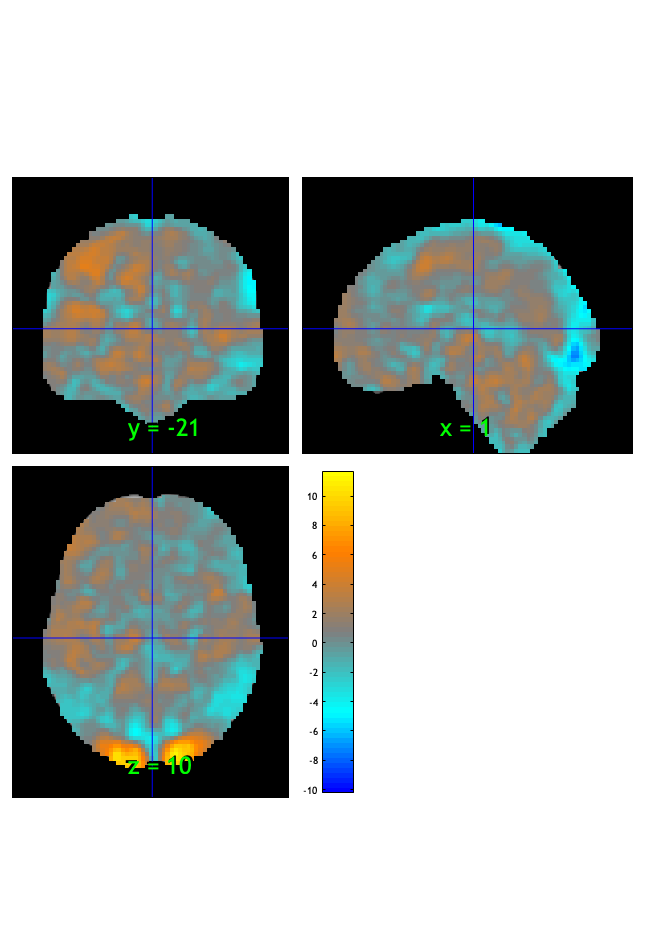

SPM12: spm_check_registration (v7759)              14:48:57 - 01/06/2022
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


ans = 1×1 cell array
    {1×1 struct}


orthviews(t)

drawnow, snapnow;

fdr_t = threshold(t, .05, 'fdr');

Image   1 FDR q < 0.050 threshold is 0.003373

Image   1
114 contig. clusters, sizes   1 to 2037
Positive effect: 4582 voxels, min p-value: 0.00000000
Negative effect: 2155 voxels, min p-value: 0.00000000


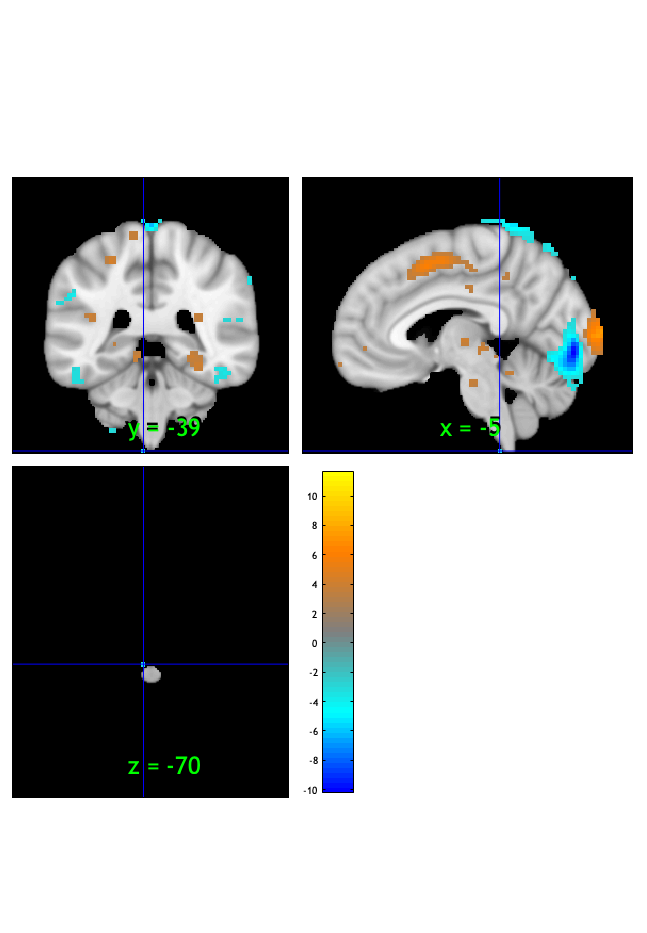

SPM12: spm_check_registration (v7759)              14:48:58 - 01/06/2022
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


ans = 1×1 cell array
    {1×114 struct}


orthviews(fdr_t)

drawnow, snapnow;

create_figure('montage'); axis off
montage(fdr_t)

Setting up fmridisplay objects


sagittal montage: 204 voxels displayed, 6533 not displayed on these slices


sagittal montage:  59 voxels displayed, 6678 not displayed on these slices


sagittal montage: 166 voxels displayed, 6571 not displayed on these slices


axial montage: 1187 voxels displayed, 5550 not displayed on these slices


axial montage: 1343 voxels displayed, 5394 not displayed on these slices


ans =   fmridisplay with properties:

            overlay: '/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img'
              SPACE: [1×1 struct]
    activation_maps: {[1×1 struct]}
            montage: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
            surface: {}
          orthviews: {}
            history: {}
    history_descrip: []
    additional_info: ''


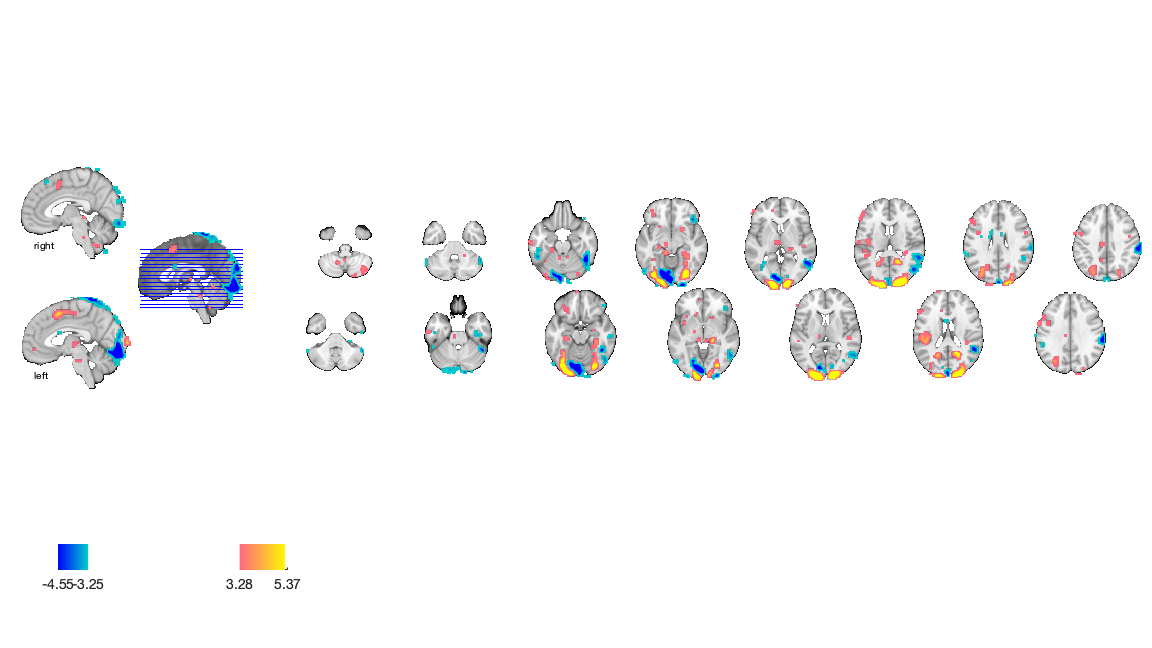

drawnow, snapnow;

## Cognitive cue

#### Cognitive :: load dataset

mount_dir = '/Volumes/spacetop_projects_social/analysis/fmri/spm/univariate/model-02_CcEScsA_24dofcsd/1stLevel';
con_list = dir(fullfile(mount_dir, '*/con_0023.nii'));
spm('Defaults','fMRI') 
con_fldr = {con_list.folder}; fname = {con_list.name};
con_files = strcat(con_fldr,'/', fname)';
con_data_obj = fmri_data(con_files);

Using default mask: /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii


sampleto = '/Volumes/spacetop_projects_social/analysis/fmri/spm/univariate/model-02_CcEScsA_24dofcsd/1stLevel/sub-0007/con_0023.nii'

loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 23960880 bytes
Loading image number:    60
Elapsed time is 6.042847 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 5791224  Bit rate: 22.47 bits


contrast_name = {'cue_P', 'cue_V', 'cue_C',...
    'cueXcue_P', 'cueXcue_V', 'cueXcue_C',...
    'stim_P', 'stim_V', 'stim_C',...
    'stimXcue_P', 'stimXcue_V', 'stimXcue_C',...
    'stimXint_P', 'stimXint_V', 'stimXint_C',...
    'motor', ...
    'simple_cue_P', 'simple_cue_V', 'simple_cue_C','simple_cue_G',...
    'simple_cueXcue_P', 'simple_cueXcue_V', 'simple_cueXcue_C','simple_cueXcue_G', ...
    'simple_stim_P', 'simple_stim_V', 'simple_stim_C','simple_stim_G',...
    'simple_stimXcue_P', 'simple_stimXcue_V', 'simple_stimXcue_C','simple_stimXcue_G',...
    'simple_stimXint_P', 'simple_stimXint_V','simple_stimXint_C', 'simple_stimXint_G'};

#### Cognitive :: `check data coverage`

SPM12: spm_check_registration (v7759)              14:49:16 - 01/06/2022
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


Grouping contiguous voxels:   1 regions


ans = 1×1 cell array
    {1×1 region}


m = mean(con_data_obj);
m.dat = sum(~isnan(con_data_obj.dat) & con_data_obj.dat ~= 0, 2);
orthviews(m, 'trans') % display

#### Cognitive :: Plot diagnostics, before l2norm

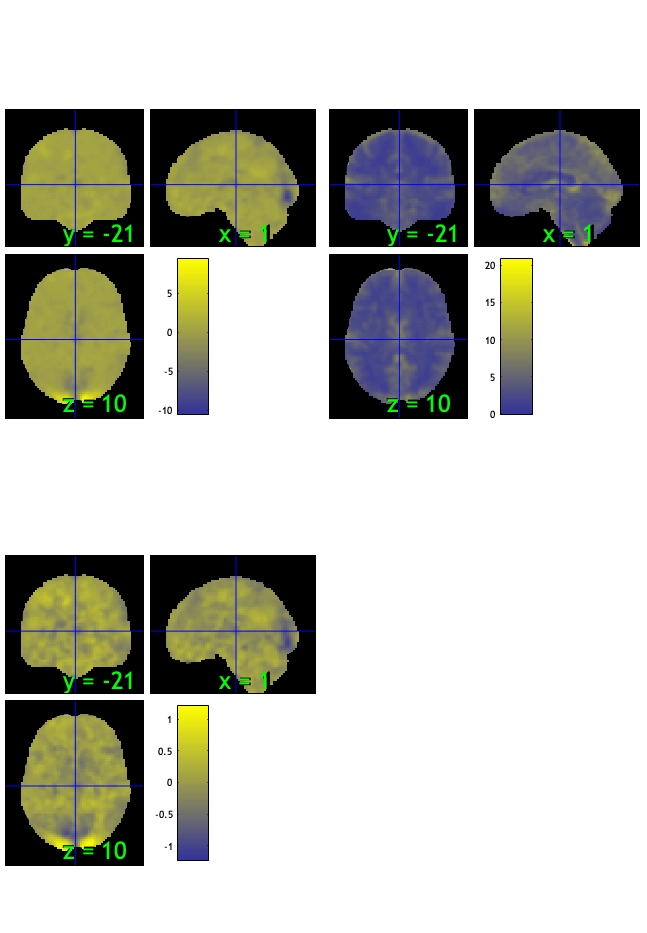

______________________________________________________________
Outlier analysis
______________________________________________________________
global mean | global mean to var | spatial MAD | Missing values |   0 images 


Retained 3 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 35.00%
Expected 3.00 outside 95% ellipsoid, found   8

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 0 images		Cases  
Uncorrected: 8 images		Cases 3 7 13 21 23 26 30 35 

Retained 13 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 46.67%
Expected 3.00 outside 95% ellipsoid, found   0

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 0 images		Cases  
Uncorrected: 0 images		Cases  

Mahalanobis (cov and corr, q<0.05 corrected):
  0 images 
                               Outlier_count    Percentage
                               _

SPM12: spm_check_registration (v7759)              14:49:36 - 01/06/2022
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1
 (all)  

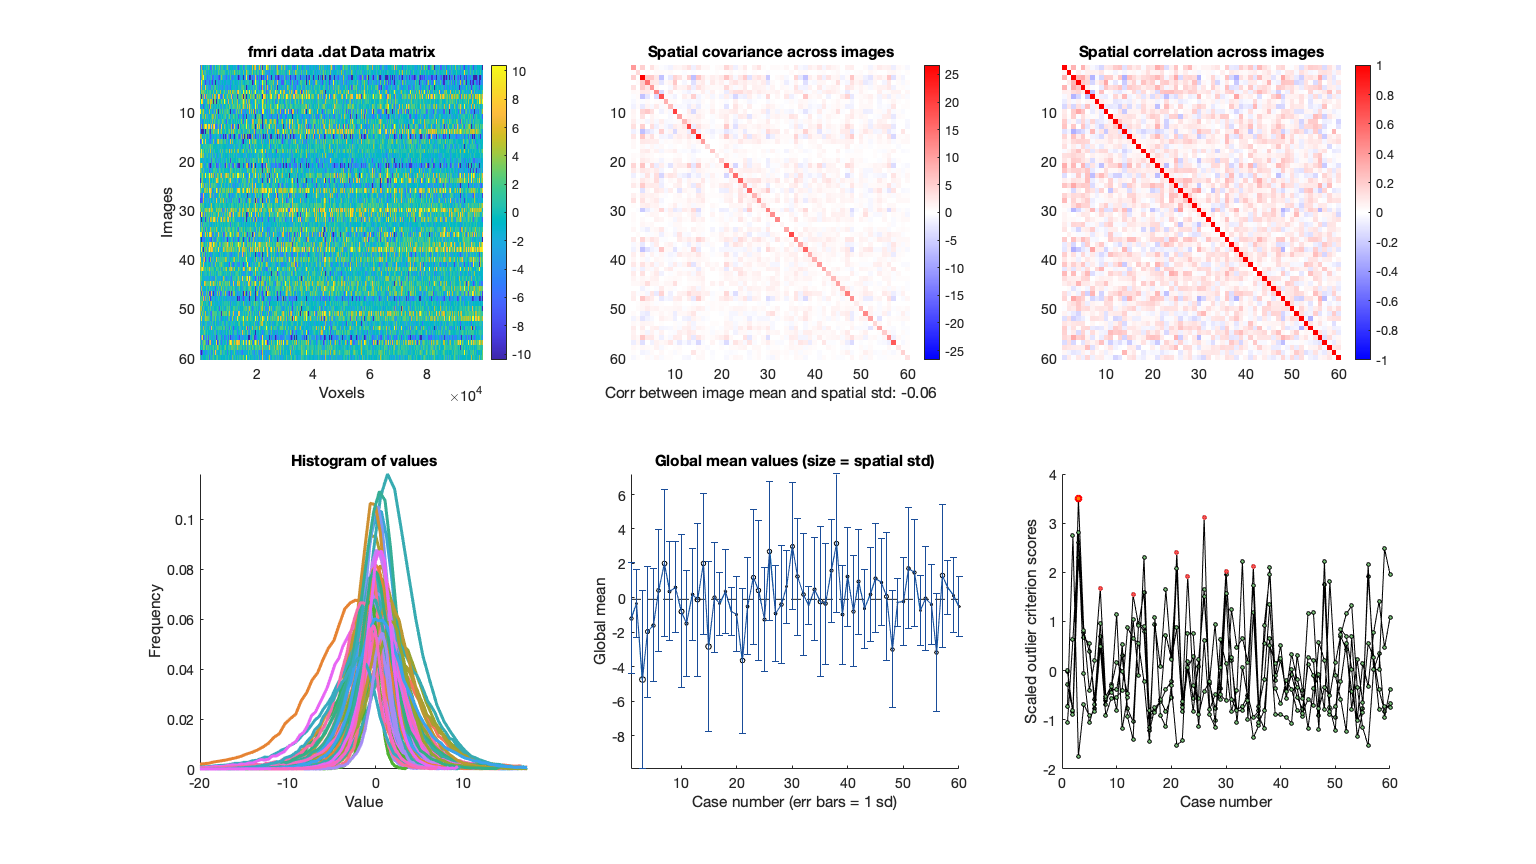

Grouping contiguous voxels:   1 regions


Grouping contiguous voxels:   1 regions


Grouping contiguous voxels:   1 regions


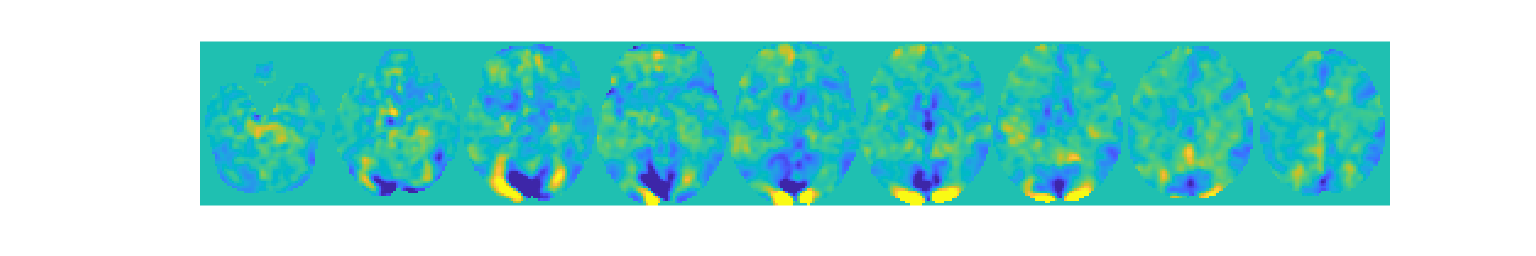

wh_outlier_uncorr = 60×1 logical array
   0
   0
   1
   0
   0
   0
   1
   0
   0
   0


wh_outlier_corr = 60×1 logical array
   0
   0
   1
   0
   0
   0
   0
   0
   0
   0


drawnow; snapnow

[wh_outlier_uncorr, wh_outlier_corr] = plot(con_data_obj)

#### Cognitive :: run robfit

set(gcf,'Visible','on')
figure ('Visible', 'on');
drawnow, snapnow;

#### Cognitive :: remove outliers based on plot

con = con_data_obj;
disp(strcat("current length is ", num2str(size(con_data_obj.dat,2))))

current length is 60


%for s = 1:length(wh_outlier_corr)
   % disp(strcat("-------subject", num2str(s), "------"))
con.dat = con_data_obj.dat(:,~wh_outlier_corr);
con.image_names = con_data_obj.image_names(~wh_outlier_corr,:)

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×59 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [59×12 char]
              fullpath: [60×119 char]
           files_exist: [60×1 logical]
               history:

con.fullpath = con_data_obj.fullpath(~wh_outlier_corr,:)

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×59 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [59×12 char]
              fullpath: [59×119 char]
           files_exist: [60×1 logical]
               history:

con.files_exist = con_data_obj.files_exist(~wh_outlier_corr,:)

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×59 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [59×12 char]
              fullpath: [59×119 char]
           files_exist: [59×1 logical]
               history:

%end
disp(strcat("after removing ", num2str(sum(wh_outlier_corr)), " participants, size is now ",num2str(size(con.dat,2))))

after removing 1 participants, size is now 59


#### Cognitive :: plot diagnostics, after l2norm

imgs2 = con.rescale('l2norm_images');

#### Cognitive :: ttest

t = ttest(imgs2);

One-sample t-test
Calculating t-statistics and p-values


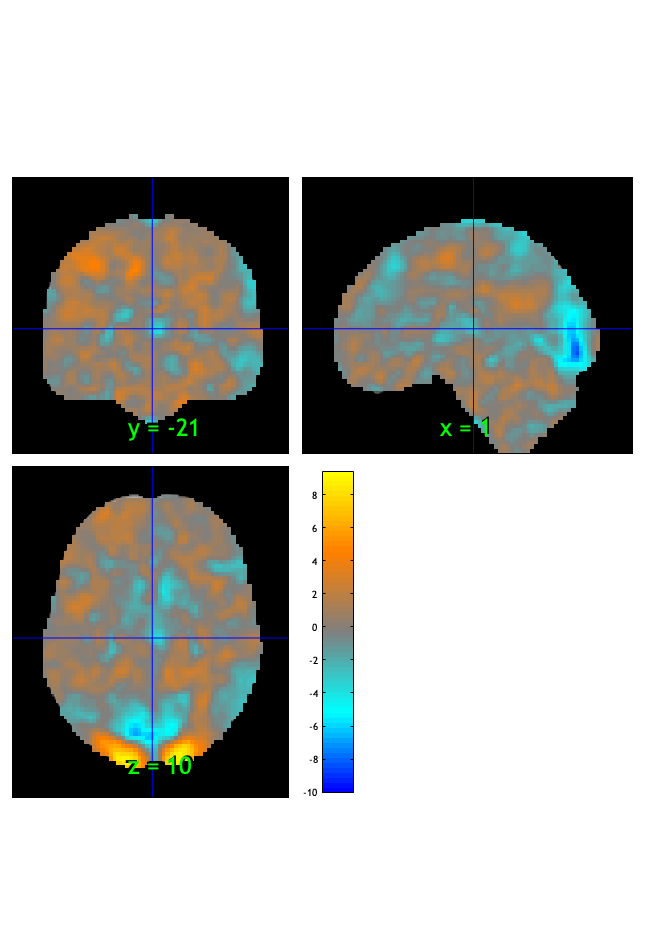

SPM12: spm_check_registration (v7759)              14:49:40 - 01/06/2022
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


ans = 1×1 cell array
    {1×1 struct}


orthviews(t)

drawnow, snapnow;

fdr_t = threshold(t, .05, 'fdr');

Image   1 FDR q < 0.050 threshold is 0.001855

Image   1
 64 contig. clusters, sizes   1 to 2290
Positive effect: 1962 voxels, min p-value: 0.00000000
Negative effect: 1742 voxels, min p-value: 0.00000000


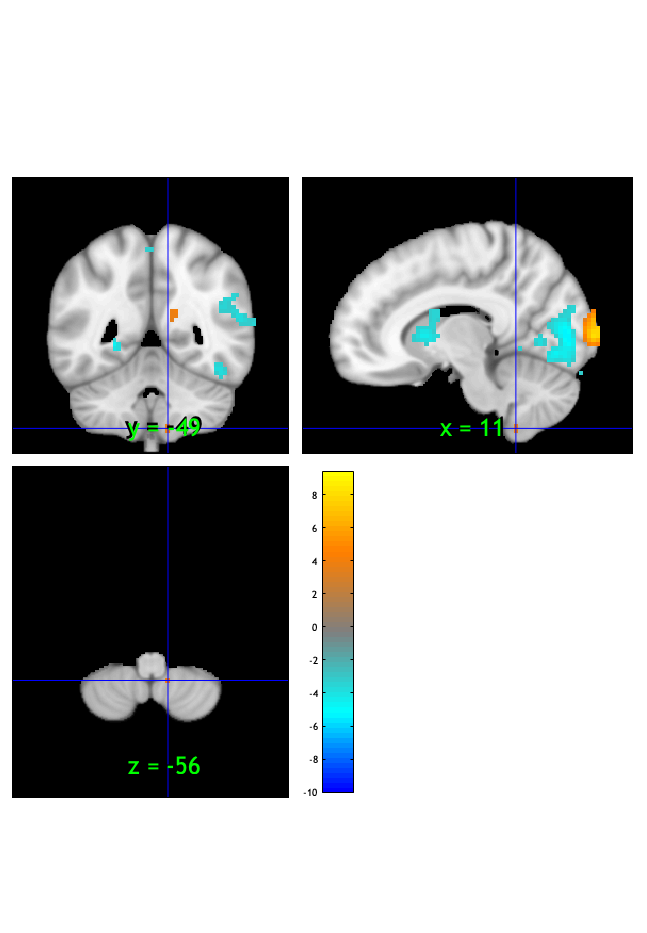

SPM12: spm_check_registration (v7759)              14:49:41 - 01/06/2022
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


ans = 1×1 cell array
    {1×64 struct}


orthviews(fdr_t)

drawnow, snapnow;

create_figure('montage'); axis off
montage(fdr_t)

Setting up fmridisplay objects


sagittal montage: 133 voxels displayed, 3571 not displayed on these slices


sagittal montage: 114 voxels displayed, 3590 not displayed on these slices


sagittal montage: 115 voxels displayed, 3589 not displayed on these slices


axial montage: 773 voxels displayed, 2931 not displayed on these slices


axial montage: 846 voxels displayed, 2858 not displayed on these slices


ans =   fmridisplay with properties:

            overlay: '/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img'
              SPACE: [1×1 struct]
    activation_maps: {[1×1 struct]}
            montage: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
            surface: {}
          orthviews: {}
            history: {}
    history_descrip: []
    additional_info: ''


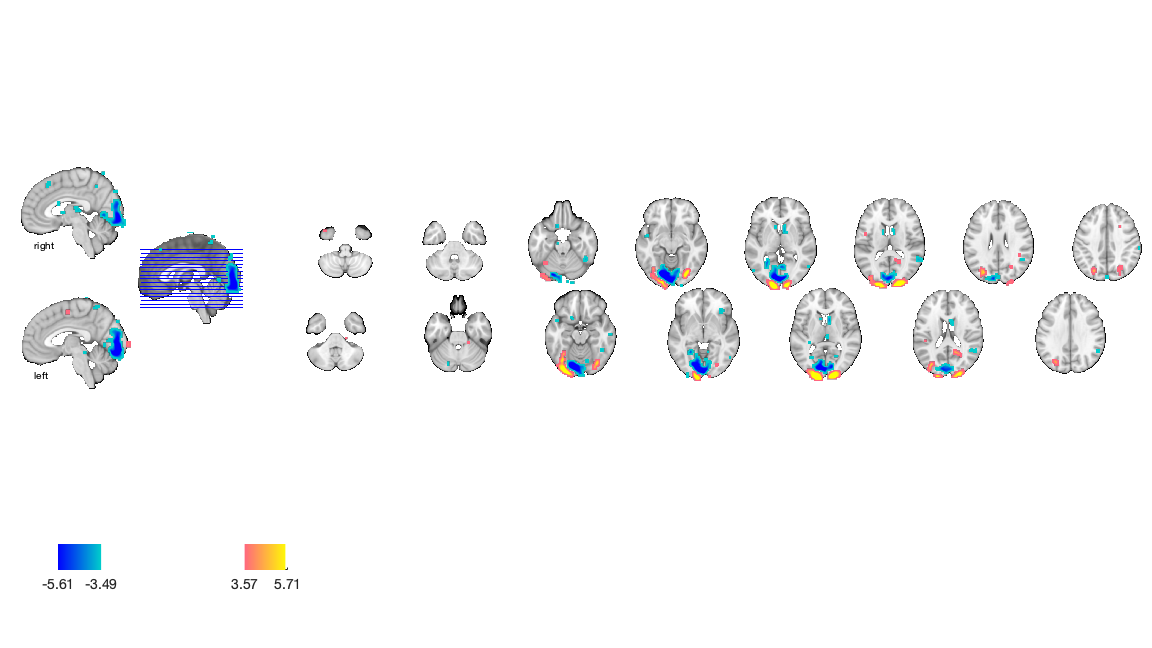

drawnow, snapnow;

#### General :: load dataset

mount_dir = '/Volumes/spacetop_projects_social/analysis/fmri/spm/univariate/model-02_CcEScsA_24dofcsd/1stLevel';
con_list = dir(fullfile(mount_dir, '*/con_0024.nii'));
spm('Defaults','fMRI') 
con_fldr = {con_list.folder}; fname = {con_list.name};
con_files = strcat(con_fldr,'/', fname)';
con_data_obj = fmri_data(con_files);

Using default mask: /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii


sampleto = '/Volumes/spacetop_projects_social/analysis/fmri/spm/univariate/model-02_CcEScsA_24dofcsd/1stLevel/sub-0007/con_0024.nii'

loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 23960880 bytes
Loading image number:    60
Elapsed time is 6.089119 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 5793764  Bit rate: 22.47 bits


contrast_name = {'cue_P', 'cue_V', 'cue_C',...
    'cueXcue_P', 'cueXcue_V', 'cueXcue_C',...
    'stim_P', 'stim_V', 'stim_C',...
    'stimXcue_P', 'stimXcue_V', 'stimXcue_C',...
    'stimXint_P', 'stimXint_V', 'stimXint_C',...
    'motor', ...
    'simple_cue_P', 'simple_cue_V', 'simple_cue_C','simple_cue_G',...
    'simple_cueXcue_P', 'simple_cueXcue_V', 'simple_cueXcue_C','simple_cueXcue_G', ...
    'simple_stim_P', 'simple_stim_V', 'simple_stim_C','simple_stim_G',...
    'simple_stimXcue_P', 'simple_stimXcue_V', 'simple_stimXcue_C','simple_stimXcue_G',...
    'simple_stimXint_P', 'simple_stimXint_V','simple_stimXint_C', 'simple_stimXint_G'};


#### General :: `check data coverage`

SPM12: spm_check_registration (v7759)              14:49:58 - 01/06/2022
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


Grouping contiguous voxels:   1 regions


ans = 1×1 cell array
    {1×1 region}


m = mean(con_data_obj);
m.dat = sum(~isnan(con_data_obj.dat) & con_data_obj.dat ~= 0, 2);
orthviews(m, 'trans') % display

#### General :: Plot diagnostics, before l2norm

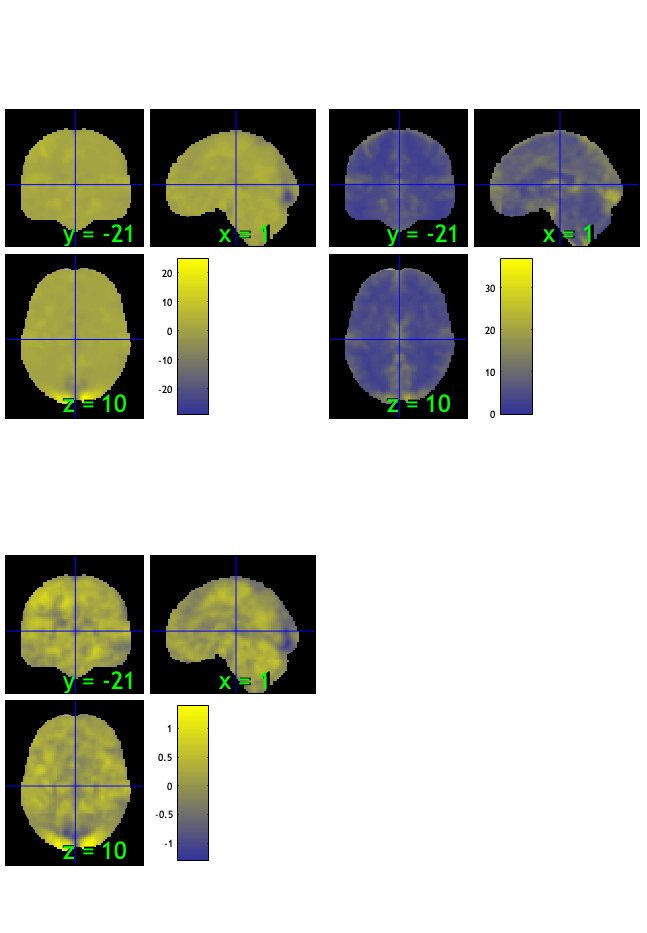

______________________________________________________________
Outlier analysis
______________________________________________________________
global mean | global mean to var | spatial MAD | Missing values |   0 images 


Retained 4 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 31.67%
Expected 3.00 outside 95% ellipsoid, found   8

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 0 images		Cases  
Uncorrected: 8 images		Cases 7 10 14 21 30 31 38 47 

Retained 17 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 45.00%
Expected 3.00 outside 95% ellipsoid, found   3

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 0 images		Cases  
Uncorrected: 3 images		Cases 8 17 60 

Mahalanobis (cov and corr, q<0.05 corrected):
  0 images 
                               Outlier_count    Percentage
                               <

SPM12: spm_check_registration (v7759)              14:50:17 - 01/06/2022
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1
 (all)  

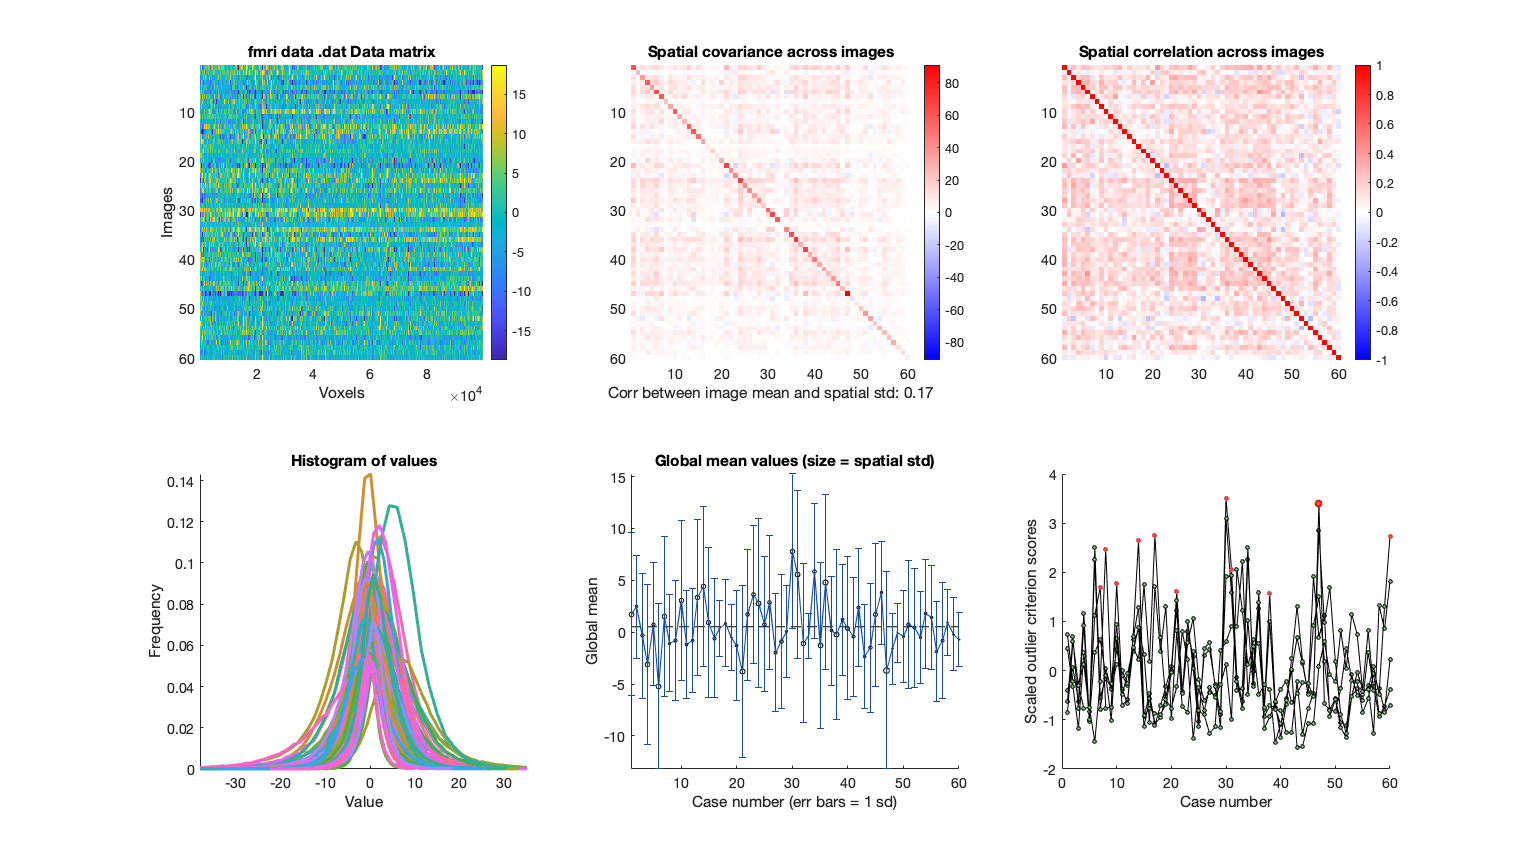

Grouping contiguous voxels:   1 regions


Grouping contiguous voxels:   1 regions


Grouping contiguous voxels:   1 regions


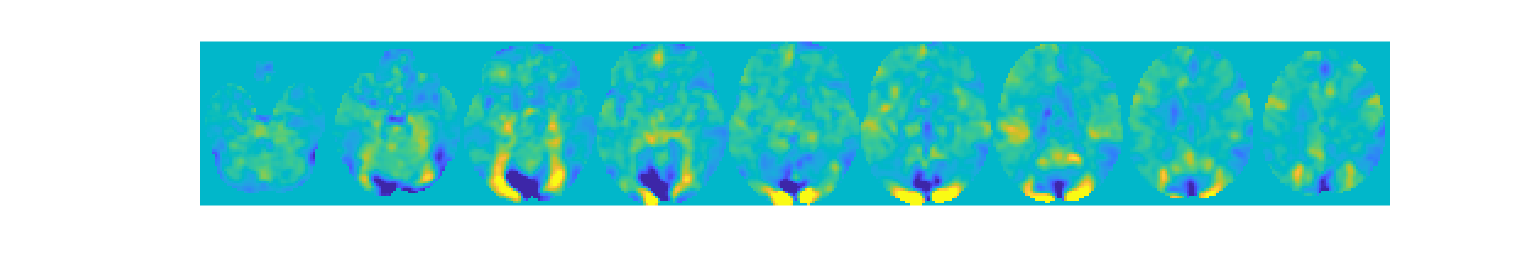

wh_outlier_uncorr = 60×1 logical array
   0
   0
   0
   0
   0
   0
   1
   1
   0
   1


wh_outlier_corr = 60×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


drawnow; snapnow

[wh_outlier_uncorr, wh_outlier_corr] = plot(con_data_obj)

#### General :: run robfit

set(gcf,'Visible','on')
figure ('Visible', 'on');
drawnow, snapnow;

#### General :: remove outliers based on plot

con = con_data_obj;
disp(strcat("current length is ", num2str(size(con_data_obj.dat,2))))

current length is 60


%for s = 1:length(wh_outlier_corr)
    %disp(strcat("-------subject", num2str(s), "------"))
con.dat = con_data_obj.dat(:,~wh_outlier_corr);
con.image_names = con_data_obj.image_names(~wh_outlier_corr,:)

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×59 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [59×12 char]
              fullpath: [60×119 char]
           files_exist: [60×1 logical]
               history:

con.fullpath = con_data_obj.fullpath(~wh_outlier_corr,:)

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×59 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [59×12 char]
              fullpath: [59×119 char]
           files_exist: [60×1 logical]
               history:

con.files_exist = con_data_obj.files_exist(~wh_outlier_corr,:)

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×59 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [59×12 char]
              fullpath: [59×119 char]
           files_exist: [59×1 logical]
               history:

%end
disp(strcat("after removing ", num2str(sum(wh_outlier_corr)), " participants, size is now ",num2str(size(con.dat,2))))

after removing 1 participants, size is now 59


#### General :: plot diagnostics, after l2norm

imgs2 = con.rescale('l2norm_images');

#### General :: ttest

t = ttest(imgs2);

One-sample t-test
Calculating t-statistics and p-values


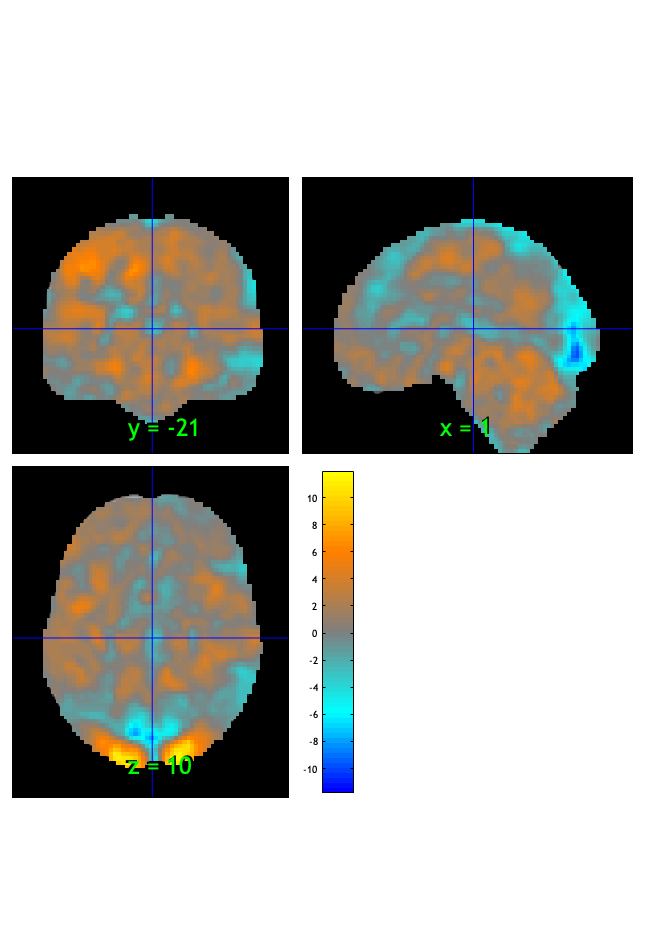

SPM12: spm_check_registration (v7759)              14:50:21 - 01/06/2022
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


ans = 1×1 cell array
    {1×1 struct}


orthviews(t)

drawnow, snapnow;

fdr_t = threshold(t, .05, 'fdr');

Image   1 FDR q < 0.050 threshold is 0.008587

Image   1
117 contig. clusters, sizes   1 to 13443
Positive effect: 13198 voxels, min p-value: 0.00000000
Negative effect: 3947 voxels, min p-value: 0.00000000


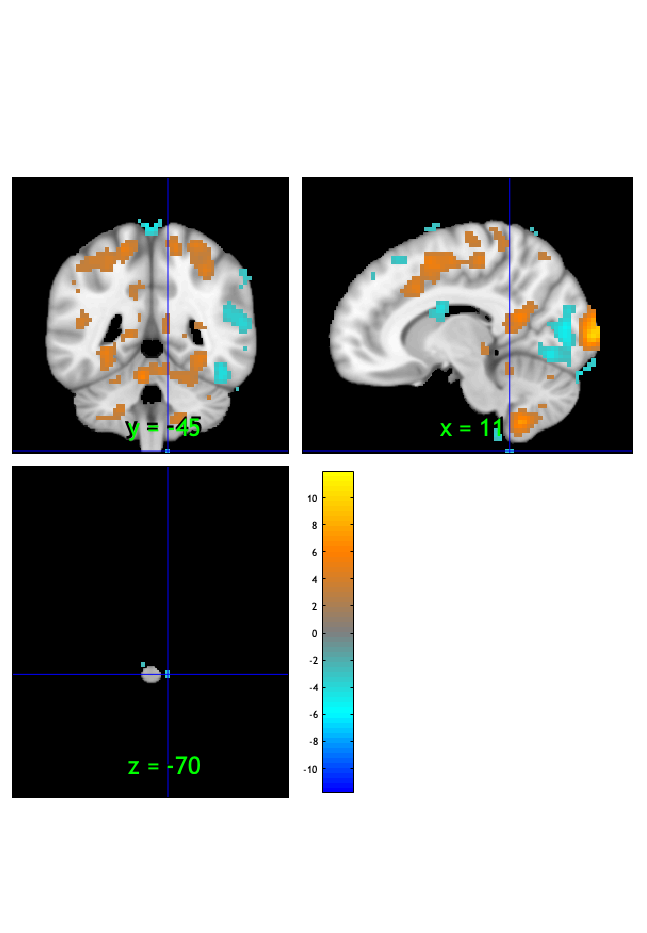

SPM12: spm_check_registration (v7759)              14:50:22 - 01/06/2022
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


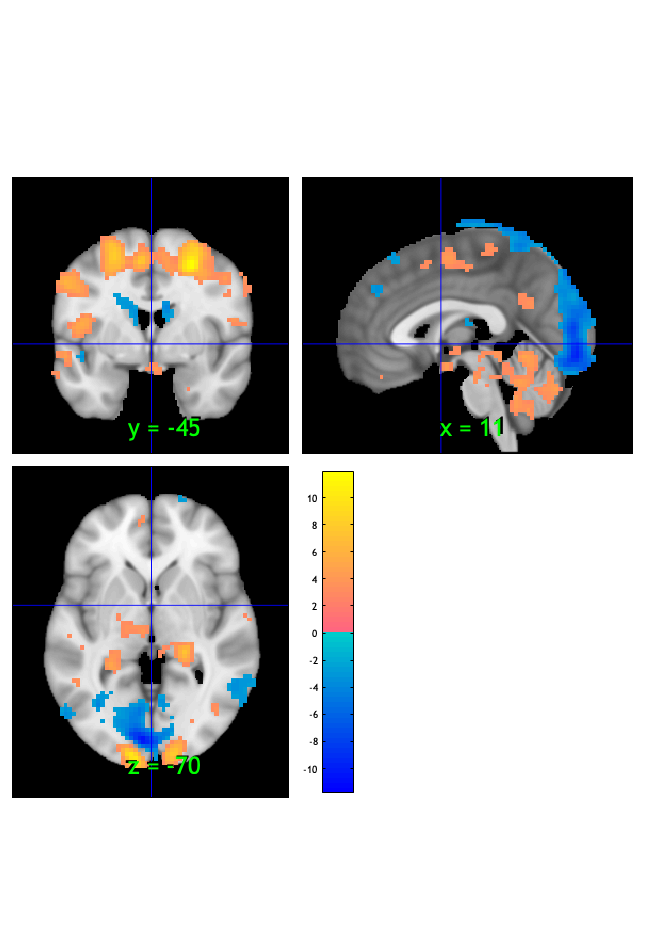

ans = 1×1 cell array
    {1×117 struct}


orthviews(fdr_t)

drawnow, snapnow;

create_figure('montage'); axis off
montage(fdr_t)

Setting up fmridisplay objects


sagittal montage: 474 voxels displayed, 16671 not displayed on these slices


sagittal montage: 461 voxels displayed, 16684 not displayed on these slices


sagittal montage: 419 voxels displayed, 16726 not displayed on these slices


axial montage: 2748 voxels displayed, 14397 not displayed on these slices


axial montage: 3296 voxels displayed, 13849 not displayed on these slices


ans =   fmridisplay with properties:

            overlay: '/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img'
              SPACE: [1×1 struct]
    activation_maps: {[1×1 struct]}
            montage: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
            surface: {}
          orthviews: {}
            history: {}
    history_descrip: []
    additional_info: ''


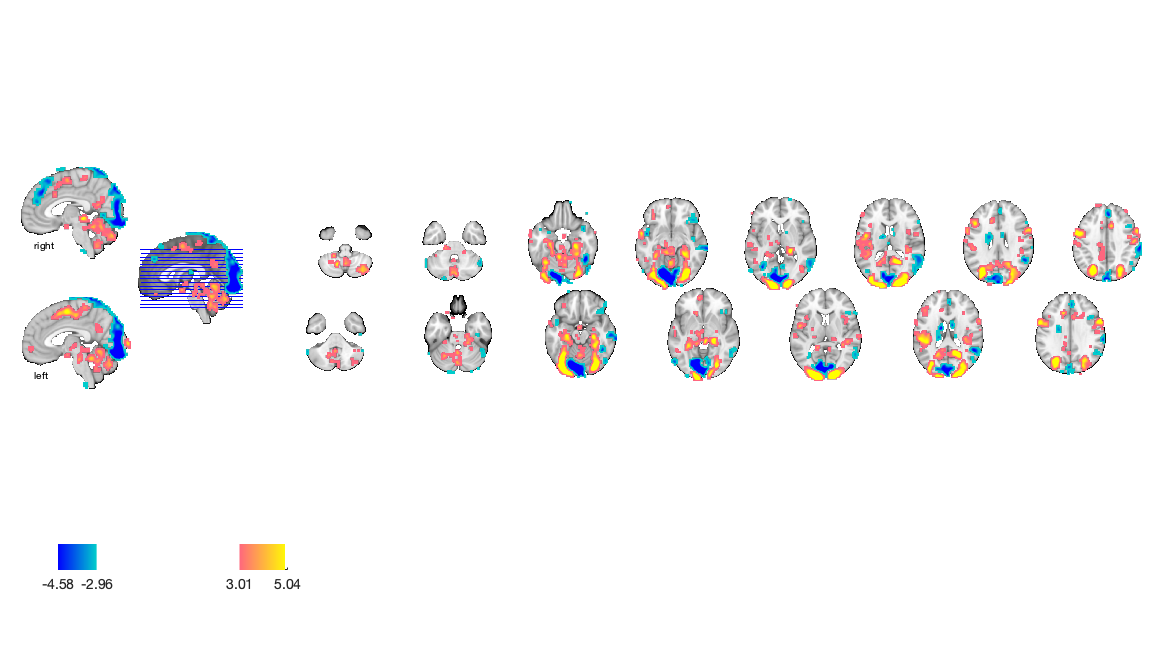

drawnow, snapnow;